## Q1 - part b | ARMAX

clear; clc;

%%

load q1_402123100.mat

u_val = u(length(u)/2+1:end);
v_val = v(length(u)/2+1:end);
z_val = z(length(u)/2+1:end);
y_val = y(length(u)/2+1:end);

u = u(1:length(u)/2);
v = v(1:length(v)/2);
z = z(1:length(z)/2);
y = y(1:length(y)/2);


%%

Ts = 0.1; 
t = 0:Ts:length(u)*Ts-Ts;
N = length(y);
data = iddata(y,u,Ts);

%%


fprintf("===============Degree Extraction | Best Fit Lowest Error Method====================\n")

===============Degree Extraction | Best Fit Lowest Error Method====================


R2s  = [];
MSEs = [];
dets = [];
vars = [];
covs = [];
S_hats = [];
AICs = [];
ps = [];
k = 5;

for degree=1:1:100
    na = degree;
    nb = degree;
    nc = degree;
    p = na+nb+nc+1;
    try
        sys = armax(data, [na nb nc 1]);
        armax_y_hat = lsim(sys, u_val, t);
    catch
        break
    end
%     armax_U = armax_U_builder(na,nb,nc,u,y,error_hat);
%     armax_theta_hat = inv(armax_U'*armax_U)*armax_U'*y;
%     armax_y_hat = armax_U*armax_theta_hat;
    
    [r2_armax, mse_armax] = rSQR(y_val, armax_y_hat);

    error = y_val - armax_y_hat;
    S_hat = 0;
    for i=1:length(error)
        S_hat = S_hat + error(i)^2;
    end
    
    AIC = AIC_criteria(S_hat, k, p, N);
    variance = Variance_criteria(S_hat, N, p);

%     theta = [sys.A sys.B sys.C];
%     covs = [covs; cov(theta)];

    fprintf(">>> Degree = %d : R2=%f | MSE=%f | var=%f |\n", degree, r2_armax, mse_armax, variance)
    fprintf("-------------------------------------------------------------\n")
    ps = [ps; p];
    S_hats = [S_hats; S_hat];
    AICs = [AICs; AIC];
    R2s = [R2s; r2_armax];
    MSEs = [MSEs; mse_armax];
    vars = [vars; variance];

end

>>> Degree = 1 : R2=0.032631 | MSE=5.357101 | var=5.400303 |


-------------------------------------------------------------


>>> Degree = 2 : R2=0.043706 | MSE=5.295767 | var=5.370961 |


-------------------------------------------------------------


>>> Degree = 3 : R2=0.821072 | MSE=0.990870 | var=1.011092 |


-------------------------------------------------------------


>>> Degree = 4 : R2=0.822038 | MSE=0.985521 | var=1.011828 |


-------------------------------------------------------------


>>> Degree = 5 : R2=0.820017 | MSE=0.996713 | var=1.029662 |


-------------------------------------------------------------


>>> Degree = 6 : R2=0.694651 | MSE=1.690961 | var=1.757756 |


-------------------------------------------------------------


>>> Degree = 7 : R2=0.510297 | MSE=2.711879 | var=2.836693 |


-------------------------------------------------------------


>>> Degree = 8 : R2=0.810596 | MSE=1.048883 | var=1.104088 |


-------------------------------------------------------------


>>> Degree = 9 : R2=-0.557017 | MSE=8.622456 | var=9.133957 |


-------------------------------------------------------------


>>> Degree = 10 : R2=0.751777 | MSE=1.374611 | var=1.465470 |


-------------------------------------------------------------


>>> Degree = 11 : R2=0.818417 | MSE=1.005571 | var=1.078939 |


-------------------------------------------------------------


>>> Degree = 12 : R2=0.803089 | MSE=1.090457 | var=1.177599 |


-------------------------------------------------------------


>>> Degree = 13 : R2=0.809914 | MSE=1.052660 | var=1.144196 |


-------------------------------------------------------------


>>> Degree = 14 : R2=0.804460 | MSE=1.082862 | var=1.184751 |


-------------------------------------------------------------


>>> Degree = 15 : R2=0.756354 | MSE=1.349261 | var=1.485970 |


-------------------------------------------------------------


>>> Degree = 16 : R2=0.814773 | MSE=1.025749 | var=1.137194 |


-------------------------------------------------------------


>>> Degree = 17 : R2=0.815708 | MSE=1.020572 | var=1.139031 |


-------------------------------------------------------------


>>> Degree = 18 : R2=0.815409 | MSE=1.022228 | var=1.148571 |


-------------------------------------------------------------


>>> Degree = 19 : R2=0.814727 | MSE=1.026006 | var=1.160641 |


-------------------------------------------------------------


>>> Degree = 20 : R2=0.816893 | MSE=1.014013 | var=1.154912 |


-------------------------------------------------------------


>>> Degree = 21 : R2=0.804673 | MSE=1.081682 | var=1.240461 |


-------------------------------------------------------------


>>> Degree = 22 : R2=0.794331 | MSE=1.138954 | var=1.315190 |


-------------------------------------------------------------


>>> Degree = 23 : R2=0.800014 | MSE=1.107484 | var=1.287772 |


-------------------------------------------------------------


>>> Degree = 24 : R2=0.790430 | MSE=1.160556 | var=1.358965 |


-------------------------------------------------------------


>>> Degree = 25 : R2=0.804238 | MSE=1.084091 | var=1.278410 |


-------------------------------------------------------------


>>> Degree = 26 : R2=0.804315 | MSE=1.083664 | var=1.287011 |


-------------------------------------------------------------


>>> Degree = 27 : R2=0.808231 | MSE=1.061977 | var=1.270307 |


-------------------------------------------------------------


>>> Degree = 28 : R2=0.805900 | MSE=1.074887 | var=1.295045 |


-------------------------------------------------------------


>>> Degree = 29 : R2=-3881.375374 | MSE=21499.835350 | var=26092.033191 |


-------------------------------------------------------------


>>> Degree = 30 : R2=0.807443 | MSE=1.066341 | var=1.303596 |


-------------------------------------------------------------


>>> Degree = 31 : R2=0.790466 | MSE=1.160361 | var=1.429016 |


-------------------------------------------------------------


>>> Degree = 32 : R2=0.796398 | MSE=1.127510 | var=1.398896 |


-------------------------------------------------------------


>>> Degree = 33 : R2=0.791481 | MSE=1.154736 | var=1.443419 |


-------------------------------------------------------------


>>> Degree = 34 : R2=0.794406 | MSE=1.138539 | var=1.433928 |


-------------------------------------------------------------


>>> Degree = 35 : R2=0.795516 | MSE=1.132391 | var=1.437045 |


-------------------------------------------------------------


>>> Degree = 36 : R2=0.792529 | MSE=1.148935 | var=1.469227 |


-------------------------------------------------------------


>>> Degree = 37 : R2=0.782962 | MSE=1.201915 | var=1.548860 |


-------------------------------------------------------------


>>> Degree = 38 : R2=0.763405 | MSE=1.310215 | var=1.701578 |


-------------------------------------------------------------


>>> Degree = 39 : R2=0.786069 | MSE=1.184706 | var=1.550663 |


-------------------------------------------------------------


>>> Degree = 40 : R2=0.788260 | MSE=1.172576 | var=1.546934 |


-------------------------------------------------------------


>>> Degree = 41 : R2=0.785208 | MSE=1.189475 | var=1.581748 |


-------------------------------------------------------------


>>> Degree = 42 : R2=0.767266 | MSE=1.288836 | var=1.727662 |


-------------------------------------------------------------


>>> Degree = 43 : R2=0.795871 | MSE=1.130428 | var=1.527606 |


-------------------------------------------------------------


>>> Degree = 44 : R2=0.792833 | MSE=1.147250 | var=1.563011 |


-------------------------------------------------------------


>>> Degree = 45 : R2=0.795873 | MSE=1.130418 | var=1.552772 |


-------------------------------------------------------------


>>> Degree = 46 : R2=0.791383 | MSE=1.155279 | var=1.600110 |


-------------------------------------------------------------


>>> Degree = 47 : R2=0.603915 | MSE=2.193441 | var=3.063465 |


-------------------------------------------------------------


>>> Degree = 48 : R2=-3928.263457 | MSE=21759.492381 | var=30647.172368 |


-------------------------------------------------------------


>>> Degree = 49 : R2=-43942891984562995193834373120.000000 | MSE=243347139707897645138572214272.000000 | var=345663550721445517063454982144.000000 |


-------------------------------------------------------------


>>> Degree = 50 : R2=0.748257 | MSE=1.394106 | var=1.997287 |


-------------------------------------------------------------


>>> Degree = 51 : R2=0.778632 | MSE=1.225895 | var=1.771525 |


-------------------------------------------------------------


>>> Degree = 52 : R2=0.751659 | MSE=1.375262 | var=2.004755 |


-------------------------------------------------------------


>>> Degree = 53 : R2=0.776786 | MSE=1.236116 | var=1.817818 |


-------------------------------------------------------------


>>> Degree = 54 : R2=0.766203 | MSE=1.294722 | var=1.920952 |


-------------------------------------------------------------


>>> Degree = 55 : R2=0.777662 | MSE=1.231265 | var=1.843210 |


-------------------------------------------------------------


>>> Degree = 56 : R2=-117505589948385622772338917376.000000 | MSE=650722970706478265540771053568.000000 | var=982965212547550231778469871616.000000 |


-------------------------------------------------------------


>>> Degree = 57 : R2=-58782.810794 | MSE=325533.244896 | var=496239.702586 |


-------------------------------------------------------------


>>> Degree = 58 : R2=0.762276 | MSE=1.316470 | var=2.025338 |


-------------------------------------------------------------


>>> Degree = 59 : R2=0.725349 | MSE=1.520965 | var=2.361747 |


-------------------------------------------------------------


>>> Degree = 60 : R2=-16396352922281238220099602139340047646720.000000 | MSE=90799795031242923371457403223718892666880.000000 | var=142319427948656661300622249849621529493504.000000 |


-------------------------------------------------------------


>>> Degree = 61 : R2=0.736022 | MSE=1.461859 | var=2.313068 |


-------------------------------------------------------------


>>> Degree = 62 : R2=0.781939 | MSE=1.207580 | var=1.929042 |


-------------------------------------------------------------


>>> Degree = 63 : R2=0.701995 | MSE=1.650291 | var=2.661760 |


-------------------------------------------------------------


>>> Degree = 64 : R2=0.769534 | MSE=1.276276 | var=2.078625 |


-------------------------------------------------------------


>>> Degree = 65 : R2=0.772066 | MSE=1.262257 | var=2.076080 |


-------------------------------------------------------------


>>> Degree = 66 : R2=-86.782837 | MSE=486.124179 | var=807.515248 |


-------------------------------------------------------------


>>> Degree = 67 : R2=-22039892443313079320576.000000 | MSE=122052612910276172316672.000000 | var=204786263272275417497600.000000 |


-------------------------------------------------------------


>>> Degree = 68 : R2=0.782060 | MSE=1.206909 | var=2.045609 |


-------------------------------------------------------------


>>> Degree = 69 : R2=-45374056948129993014470914236675719375274316398592.000000 | MSE=251272651311834206841546769092053165425658939047936.000000 | var=430261389232592773843629887752580032745832137621504.000000 |


-------------------------------------------------------------


>>> Degree = 70 : R2=0.746436 | MSE=1.404189 | var=2.429393 |


-------------------------------------------------------------


>>> Degree = 71 : R2=0.702898 | MSE=1.645294 | var=2.876387 |


-------------------------------------------------------------


>>> Degree = 72 : R2=-Inf | MSE=Inf | var=Inf |


-------------------------------------------------------------



fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | BestFit Method=================\n")

===============Degree Extraction | BestFit Method=================



bestFitDegree = find(S_hats == min(S_hats));

fprintf(">>> Looking for the minimum SSE , leads to: \n")

>>> Looking for the minimum SSE , leads to: 


fprintf("    Degree = %d \n", bestFitDegree)

    Degree = 4 


na = bestFitDegree;
nb = bestFitDegree;
nc = bestFitDegree;
p = na+nb+nc+1;

BestFitModel = armax(data, [na nb nc 1])

BestFitModel =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)          
  A(z) = 1 - 1.921 z^-1 + 0.1017 z^-2 + 1.593 z^-3 - 0.7716 z^-4   
                                                                   
  B(z) = -0.02185 z^-1 + 0.07827 z^-2 - 0.06685 z^-3 + 0.02848 z^-4
                                                                   
  C(z) = 1 - 1.964 z^-1 + 0.08861 z^-2 + 1.731 z^-3 - 0.8545 z^-4  
                                                                   
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=4   nb=4   nc=4   nk=1
   Number of free coefficients: 12
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 53.61% (prediction focus)
FPE: 0.9489, MSE: 0.9044                         


BestFit_y_hat = lsim(BestFitModel, u_val, t);
% [armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);


%%
fprintf("===============Degree Extraction | Variance Method====================\n")

===============Degree Extraction | Variance Method====================



minVarIndex = find(vars == min(vars));
fprintf(">>> Since the minimum variance value occurs in iteration %d ;\n", minVarIndex)

>>> Since the minimum variance value occurs in iteration 3 ;


fprintf("    Degree = %d \n", minVarIndex)

    Degree = 3 


na = minVarIndex;
nb = minVarIndex;
nc = minVarIndex;
p = na+nb+nc+1;

armax_VarModel = armax(data, [na nb nc 1])

armax_VarModel =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.842 z^-1 + 2.7 z^-2 - 0.8569 z^-3         
                                                         
  B(z) = 0.002931 z^-1 + 0.006859 z^-2 - 0.000951 z^-3   
                                                         
  C(z) = 1 - 2.916 z^-1 + 2.841 z^-2 - 0.9255 z^-3       
                                                         
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 53.33% (prediction focus)
FPE: 0.9488, MSE: 0.9153                         


Var_y_hat = lsim(armax_VarModel, u_val, t);
% [armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);

fprintf("=================================================================\n")


%%

% fprintf("===============Degree Extraction | CoVariance Method=================\n")
% 
% maxCovIndex = find(covs == min(covs),1);
% fprintf(">>> Since the maximum accuracy occurs in iteration %d ;\n", maxCovIndex)
% fprintf("    Degree = %d \n", maxCovIndex)
% na = maxCovIndex;
% nb = maxCovIndex;
% nc = maxCovIndex;
% p = na+nb+nc+1;
% 
% armax_CovModel = armax(data, [na nb nc 1]);
% Cov_y_hat = lsim(armax_CovModel, u_val, t);
% 
% fprintf("=================================================================\n")



%%

fprintf("===============Degree Extraction | AIC Method====================\n")

===============Degree Extraction | AIC Method====================



minAICIndex = find(AICs == min(AICs));
fprintf(">>> Since the minimum AIC value (k=%.2f) occurs in iteration %d ;\n", k, minAICIndex)

>>> Since the minimum AIC value (k=5.00) occurs in iteration 3 ;


fprintf("    Degree = %d \n", minAICIndex)

    Degree = 3 



na = minAICIndex;
nb = minAICIndex;
nc = minAICIndex;
p = na+nb+nc+1;

armax_AICModel = armax(data, [na nb nc 1])

armax_AICModel =
Discrete-time ARMAX model: A(z)y(t) = B(z)u(t) + C(z)e(t)
  A(z) = 1 - 2.842 z^-1 + 2.7 z^-2 - 0.8569 z^-3         
                                                         
  B(z) = 0.002931 z^-1 + 0.006859 z^-2 - 0.000951 z^-3   
                                                         
  C(z) = 1 - 2.916 z^-1 + 2.841 z^-2 - 0.9255 z^-3       
                                                         
Sample time: 0.1 seconds
  
Parameterization:
   Polynomial orders:   na=3   nb=3   nc=3   nk=1
   Number of free coefficients: 9
   Use "polydata", "getpvec", "getcov" for parameters and their uncertainties.

Status:                                          
Estimated using ARMAX on time domain data "data".
Fit to estimation data: 53.33% (prediction focus)
FPE: 0.9488, MSE: 0.9153                         


AIC_y_hat = lsim(armax_AICModel, u_val, t);
% [armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);

fprintf("=================================================================\n")


%%

fprintf("===============Degree Extraction | F test Method====================\n")

===============Degree Extraction | F test Method====================


winScore = 0;
winner = 1;
for i=2:length(ps)
    first = winner;
    second = i;
    winScore = finv(0.95, ps(second)-ps(first), N-ps(first));
    score = ((S_hats(first)-S_hats(second))/(ps(second)-ps(first)))/((S_hats(first))/(N-ps(first)));
    if score > winScore
        winner = i;
    end
end
fprintf(">>> The F test is suggesting the best model with the m=%.2f as\n", winScore)

>>> The F test is suggesting the best model with the m=1.21 as


fprintf("    Degree = %d \n", winner)

    Degree = 3 



na = winner;
nb = winner;
nc = winner;
p = na+nb+nc+1;

armax_FTestModel = armax(data, [na nb nc 1]);
FTest_y_hat = lsim(armax_FTestModel, u_val, t);
% [armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("=================================================================\n")

%%

[armax_BestFit_r2, armax_BestFit_mse] = rSQR(y_val, BestFit_y_hat);
[armax_Var_r2, armax_Var_mse] = rSQR(y_val, Var_y_hat);
[armax_AIC_r2, armax_AIC_mse] = rSQR(y_val, AIC_y_hat);
% [armax_Cov_r2, armax_Cov_mse] = rSQR(y_val, Cov_y_hat);
[armax_FTest_r2, armax_FTest_mse] = rSQR(y_val, FTest_y_hat);

fprintf("===================Evaluation | R2 Metric======================\n")

===================Evaluation | R2 Metric======================


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> BestFit Lowest Error Method:\n")

>>> BestFit Lowest Error Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_BestFit_r2, armax_BestFit_mse)

    R2 value : 0.8220   | MSE : 0.9855 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> Variance Method:\n")

>>> Variance Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Var_r2, armax_Var_mse)

    R2 value : 0.8211   | MSE : 0.9909 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Covariance Method:\n")
% fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_Cov_r2, armax_Cov_mse)
% fprintf("---------------------------------------------------------------\n")
fprintf(">>> AIC Method:\n")

>>> AIC Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_AIC_r2, armax_AIC_mse)

    R2 value : 0.8211   | MSE : 0.9909 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


fprintf(">>> FTest Method:\n")

>>> FTest Method:


fprintf("    R2 value : %.4f   | MSE : %.4f \n", armax_FTest_r2, armax_FTest_mse)

    R2 value : 0.8211   | MSE : 0.9909 


fprintf("---------------------------------------------------------------\n")

---------------------------------------------------------------


% fprintf(">>> Winner:\n")
% fprintf("    The best R2 value is \n")
fprintf("===============================================================\n")


%%

armax_BestFitError = y_val - BestFit_y_hat;
armax_VarError = y_val - Var_y_hat;
armax_AICError = y_val - AIC_y_hat;
% armax_CovError = y_val - Cov_y_hat;
armax_FTestError = y_val - FTest_y_hat;

for k=0:N-1
    armax_BestFit_Ree(k+1,1) = AutoCorrelate(armax_BestFitError, k);
    armax_Var_Ree(k+1,1) = AutoCorrelate(armax_VarError, k);
    armax_AIC_Ree(k+1,1) = AutoCorrelate(armax_AICError, k);
%     armax_Cov_Ree(k+1,1) = AutoCorrelate(armax_CovError, k);
    armax_FTest_Ree(k+1,1) = AutoCorrelate(armax_FTestError, k);
end

for k=0:N-1
    armax_BestFit_Rue(k+1,1) = CrossCorrelate(u_val, armax_BestFitError, k);
    armax_Var_Rue(k+1,1) = CrossCorrelate(u_val, armax_VarError, k);
    armax_AIC_Rue(k+1,1) = CrossCorrelate(u_val, armax_AICError, k);
%     armax_Cov_Rue(k+1,1) = CrossCorrelate(u_val, armax_CovError, k);
    armax_FTest_Rue(k+1,1) = CrossCorrelate(u_val, armax_FTestError, k);
end


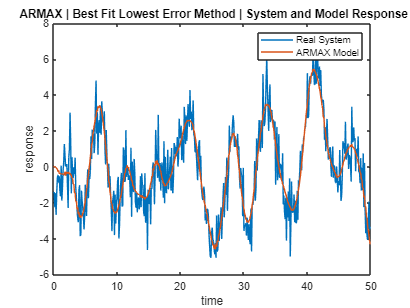

%%
figure(1)
plot(t,y_val,t,BestFit_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | Best Fit Lowest Error Method | System and Model Response")
xlabel("time")
ylabel("response")

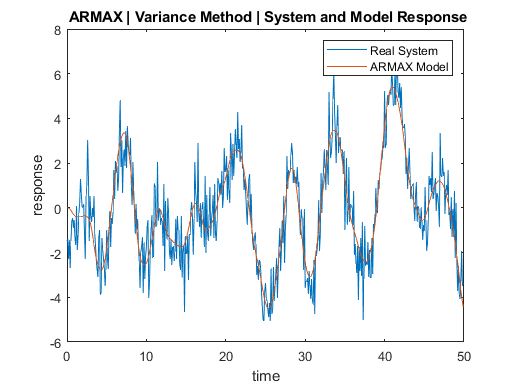


figure(2)
plot(t,y_val,t,Var_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | Variance Method | System and Model Response")
xlabel("time")
ylabel("response")

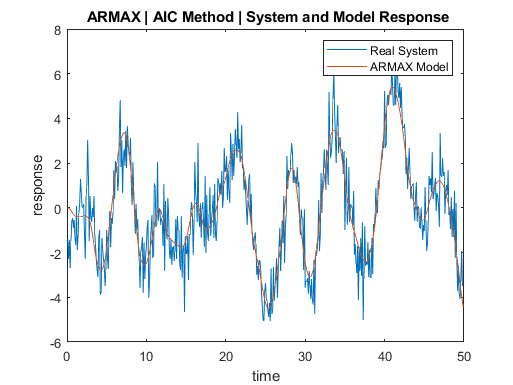


figure(3)
plot(t,y_val,t,AIC_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | AIC Method | System and Model Response")
xlabel("time")
ylabel("response")

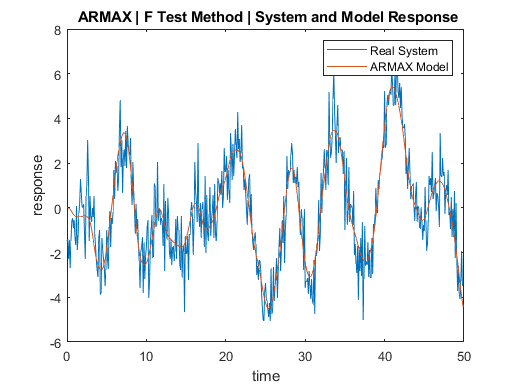


figure(4)
plot(t,y_val,t,FTest_y_hat)
legend('Real System','ARMAX Model')
title(" ARMAX | F Test Method | System and Model Response")
xlabel("time")
ylabel("response")


% figure(7)
% plot(t,y_val,t,Cov_y_hat)
% legend('Real System','ARMAX Model')
% title(" ARMAX | CoVariance Method | System and Model Response")
% xlabel("time")
% ylabel("response")

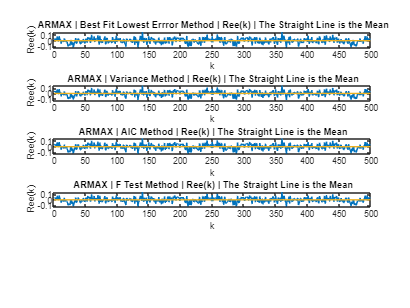


%%

figure(5)
subplot(5,1,1)
plot(1:N-1,armax_BestFit_Ree(2:end), 1:N-1, mean(armax_BestFit_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | Best Fit Lowest Errror Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,2)
plot(1:N-1,armax_Var_Ree(2:end), 1:N-1, mean(armax_Var_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | Variance Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,3)
plot(1:N-1,armax_AIC_Ree(2:end), 1:N-1, mean(armax_AIC_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | AIC Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")

subplot(5,1,4)
plot(1:N-1,armax_FTest_Ree(2:end), 1:N-1, mean(armax_FTest_Ree(2:end))*ones(length(1:N-1)))
title(" ARMAX | F Test Method | Ree(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Ree(k)")


% subplot(5,1,5)
% plot(1:N-1,armax_Cov_Ree(2:end), 1:N-1, mean(armax_Cov_Ree(2:end))*ones(length(1:N-1)))
% title(" ARMAX | CoVariance Method | Ree(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Ree(k)")

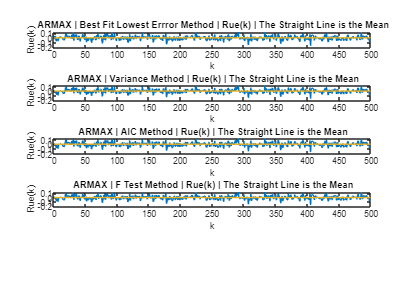

%%

figure(6)
subplot(5,1,1)
plot(1:N-1,armax_BestFit_Rue(2:end), 1:N-1, mean(armax_BestFit_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | Best Fit Lowest Errror Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(5,1,2)
plot(1:N-1,armax_Var_Rue(2:end), 1:N-1, mean(armax_Var_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | Variance Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(5,1,3)
plot(1:N-1,armax_AIC_Rue(2:end), 1:N-1, mean(armax_AIC_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | AIC Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")

subplot(5,1,4)
plot(1:N-1,armax_FTest_Rue(2:end), 1:N-1, mean(armax_FTest_Rue(2:end))*ones(length(1:N-1)))
title(" ARMAX | F Test Method | Rue(k) | The Straight Line is the Mean")
xlabel("k")
ylabel("Rue(k)")


% subplot(5,1,5)
% plot(1:N-1,armax_Cov_Rue(2:end), 1:N-1, mean(armax_Cov_Rue(2:end))*ones(length(1:N-1)))
% title(" ARMAX | CoVariance Method | Rue(k) | The Straight Line is the Mean")
% xlabel("k")
% ylabel("Rue(k)")